close all
clear
clc

定义开环系统

AF = zpk([],[0,-2,-4],1);

绘制根轨迹

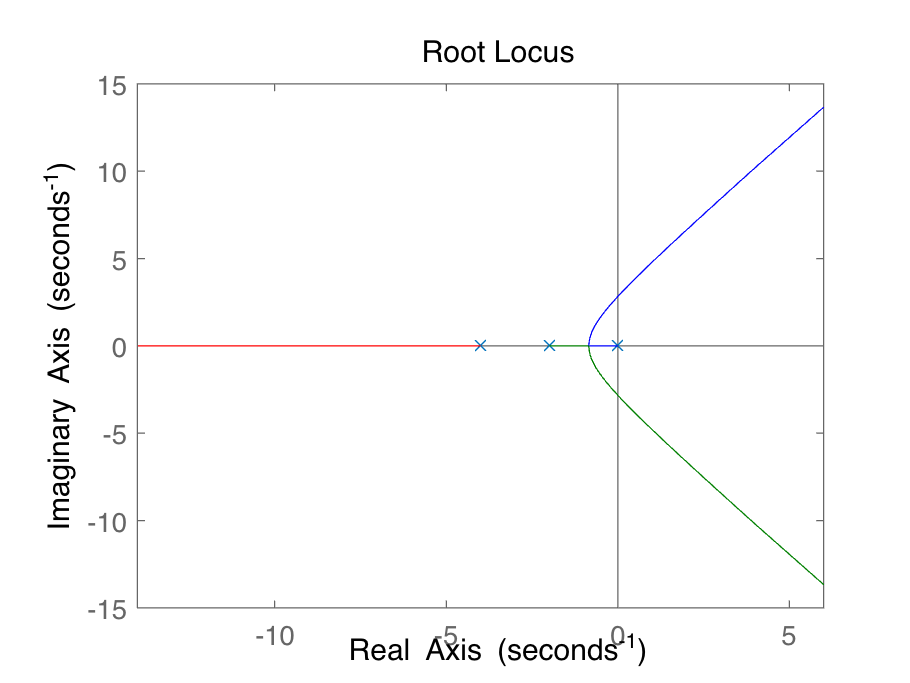

rlocus(AF);

获取根轨迹：增益k及其对应的极点r

[r,k] = rlocus(AF);

逐渐缩小网格，寻找保证极点在左半平面的最大的k

dk = 1;
while dk > 0.001
    maxrealr = max(real(r),[],1);
    idx = sum(maxrealr<=0);
    dk = [k(idx+1)-k(idx)]/16;
    [r,k] = rlocus(AF,[k(idx):dk:k(idx+1)]);
end
maxrealr = max(real(r),[],1);
idx = sum(maxrealr<=0);
disp(['K<',num2str(k(idx)),'时系统稳定']);

K<47.9999时系统稳定
